# **Interpolation using **`polyfit`

**1) Let's assume y = 0.5e^(0.1x) + 2        Let's plot this function from x = 0 to 40**

xx = 0:1:40;
yy = 0.5 * exp(0.1*xx) + 2

yy =     2.5000    2.5526    2.6107    2.6749    2.7459    2.8244    2.9111    3.0069    3.1128    3.2298    3.3591    3.5021    3.6601    3.8346    4.0276    4.2408    4.4765    4.7370    5.0248    5.3429    5.6945    6.0831    6.5125    6.9871    7.5116    8.0912    8.7319    9.4399   10.2223   11.0871   12.0428   13.0990   14.2663   15.5563   16.9821   18.5577   20.2991   22.2237   24.3506   26.7012   29.2991


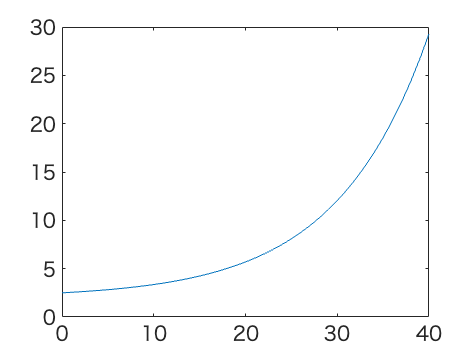


plot(xx, yy, '-')

 **2) Now let's assume that we don't know this function, but we know only some points on this function. **

# Linear

**For example, if we only know 2 points with equal interval between 0 and 40, then we can use ****linear**** interpolation to predict the unknown function**

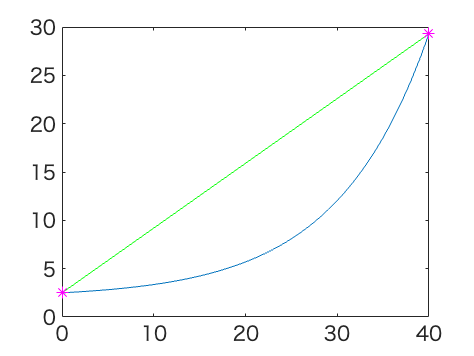

x = linspace(0, 40, 2)';
y = 0.5 * exp(0.1*x) + 2;

poly_order_1 = polyfit(x, y, 1);
xx1 = 0:1:40;
yy1 = polyval(poly_order_1, xx1);
plot(xx, yy, '-')
hold on
plot(xx1, yy1, 'g-', x, y, 'm*')
hold off

# Quadratic

**3) Now assume that we only know 3 points with equal interval between 0 and 40, then we can use ****quadratic**** interpolation to predict the unknown function**

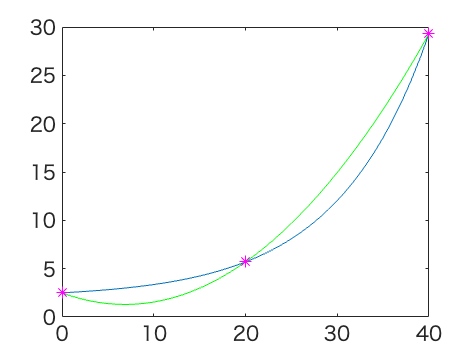

x = linspace(0, 40, 3)';
y = 0.5 * exp(0.1*x) + 2;

poly_order_2 = polyfit(x, y, 2);
xx2 = 0:1:40;
yy2 = polyval(poly_order_2, xx2);
plot(xx, yy, '-')
hold on
plot(xx2, yy2, 'g-', x, y, 'm*')
hold off

# Cubic

**4) Now assume that we only know 4 points with equal interval between 0 and 40, then we can use ****cubic**** interpolation to predict the unknown function**

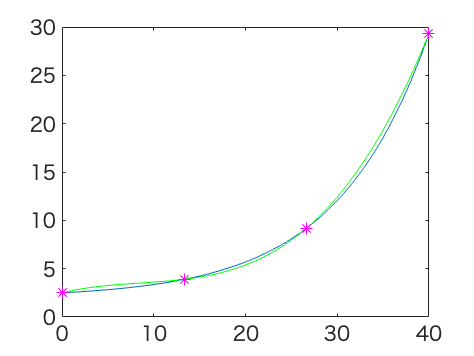

x = linspace(0, 40, 4)';
y = 0.5 * exp(0.1*x) + 2;

poly_order_3 = polyfit(x, y, 3);
xx3 = 0:1:40;
yy3 = polyval(poly_order_3, xx3);
plot(xx, yy, '-')
hold on
plot(xx3, yy3, 'g-', x, y, 'm*')
hold off